Image: External image (144x176x3), sigma: 20.0
FINAL ESTIMATE (total time: 0.5 sec), PSNR: 10.55 dB


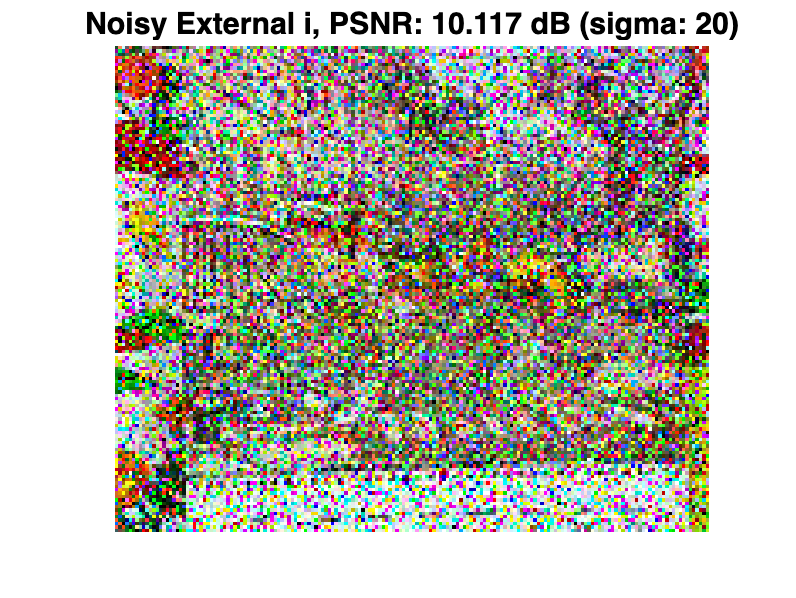

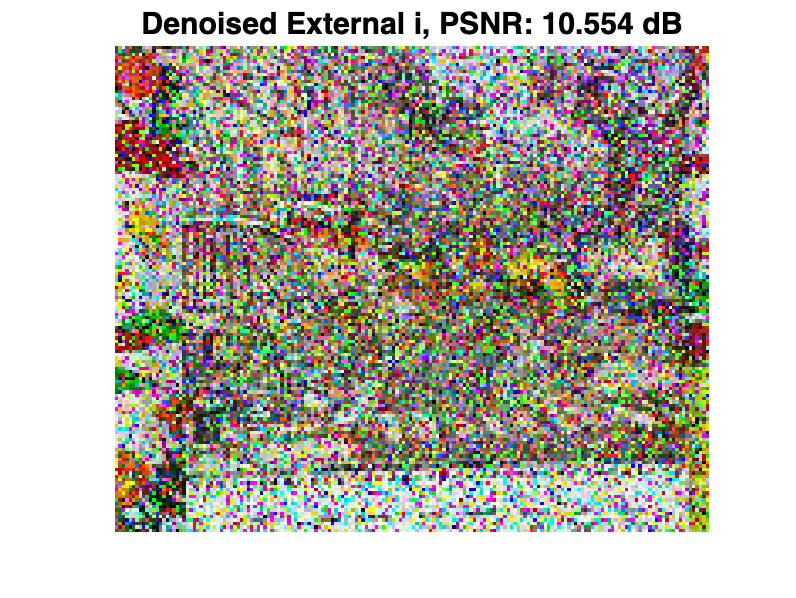

clc;
clear;
close all;

addpath("BM3D");

vid = yuv4mpeg2mov('../Test_Videos/mobile_calendar_422_qcif.y4m');

[n1,n2,~]=size(vid(1).cdata);
no_of_frames= 25; 
frame_num=15;
tau = 1.5;
iters=30;
frames_coloured=uint8(zeros([n1 n2 3 no_of_frames]));
noisy_frames_coloured=uint8(zeros([n1 n2 3 no_of_frames]));
filtered_frames_coloured=uint8(zeros([n1 n2 3 no_of_frames]));
for i=1:no_of_frames
    frames_coloured(:,:,:,i)= vid(i).cdata;
    noisy_frames_coloured(:,:,:,i) = noise(frames_coloured(:,:,:,i), 20, 2, 0.3);
    filtered_frames_coloured(:,:,1,i) = adaptive_median_filter(noisy_frames_coloured(:,:,1,i),10);
    filtered_frames_coloured(:,:,2,i) = adaptive_median_filter(noisy_frames_coloured(:,:,2,i),10);
    filtered_frames_coloured(:,:,3,i) = adaptive_median_filter(noisy_frames_coloured(:,:,3,i),10);
end
[PSNR_1, Y_without_filter] = CBM3D(frames_coloured(:,:,:,frame_num),noisy_frames_coloured(:,:,:,frame_num),20);

Image: External image (144x176x3), sigma: 20.0
FINAL ESTIMATE (total time: 0.4 sec), PSNR: 19.62 dB


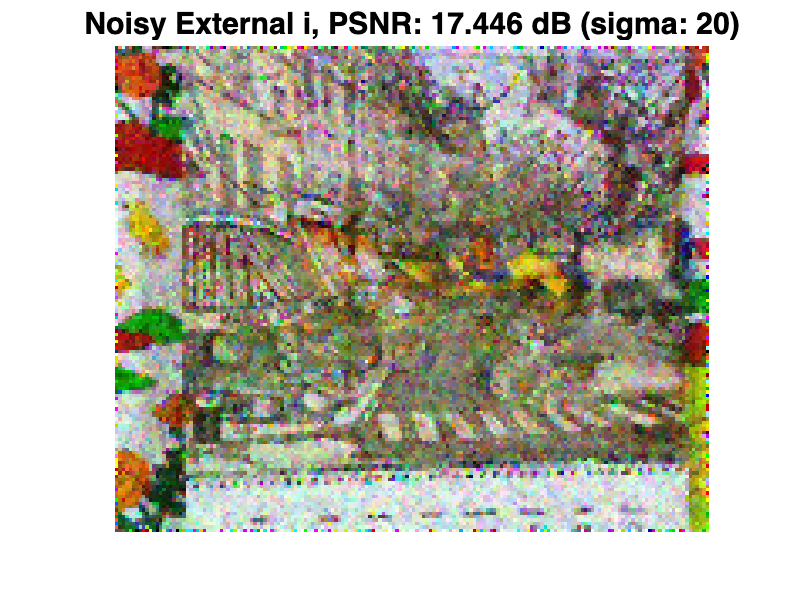

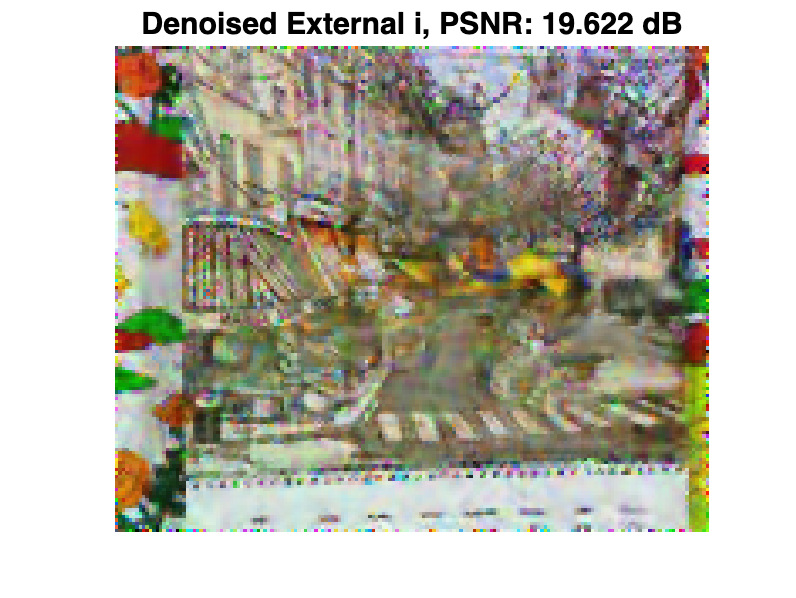

[PSNR_2, Y_with_filter] = CBM3D(frames_coloured(:,:,:,frame_num),filtered_frames_coloured(:,:,:,frame_num),20);

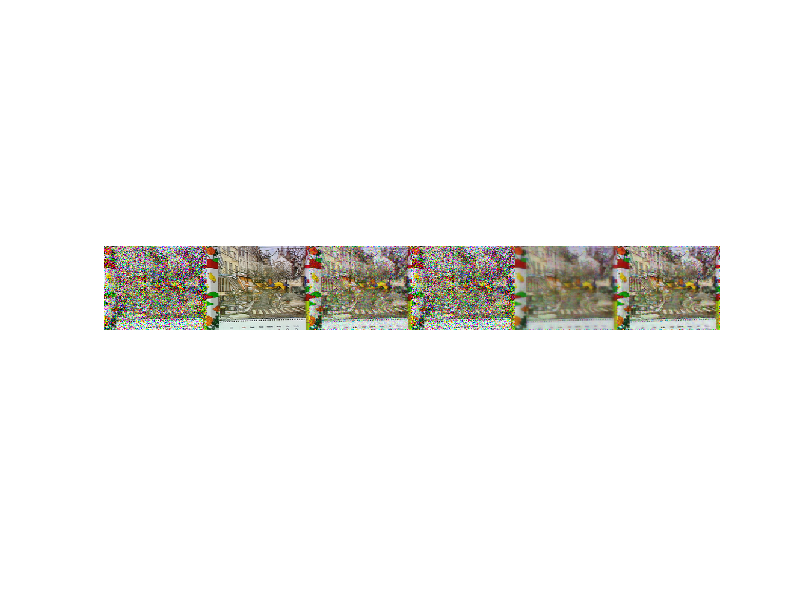

Y_without_filter = Y_without_filter*255;
Y_with_filter = Y_with_filter*255;

recon_coloured=zeros([n1 n2 3]);

for colour = 1:3 %Following the algorithm for each colour
    frames = frames_coloured(:,:,colour,:);
    filtered_frames = filtered_frames_coloured(:,:,colour,:);
    noisy_frames = noisy_frames_coloured(:,:,colour,:);

    missing_pixels = (filtered_frames == noisy_frames);
    patches = uint8(zeros([8*8 n1/4-1 n2/4-1 no_of_frames]));
    missing = false([8*8 n1/4-1 n2/4-1 no_of_frames]);

    for i=no_of_frames
        for j=1:n1
            mean_row = mean(double(filtered_frames(j,:,i)));
            std_row = std(double(filtered_frames(j,:,i)));
            for k=1:n2
                if(missing_pixels(j,k,i) > mean_row + 2*std_row || missing_pixels(j,k,i) < mean_row - 2*std_row) %For second subset of missing values
                    missing_pixels(j,k,i)=false;
                end
            end
        end
    end
    
    for i=1:no_of_frames
       for j = 1:(n1/4-1)
           for k = 1:(n2/4-1)
               patches(:,j,k,i) = reshape(filtered_frames(4*(j-1)+1:4*(j-1)+8 , 4*(k-1)+1:4*(k-1)+8, i), [64 1]);
               missing(:,j,k,i) = reshape(missing_pixels(4*(j-1)+1:4*(j-1)+8 , 4*(k-1)+1:4*(k-1)+8, i), [64 1]);    
           end
       end
    end
    
    denoised_patches = double(zeros([8*8 n1/4-1 n2/4-1 no_of_frames]));
    for j=1:n1/4-1
        for k=1:n2/4-1
            [patch_matrix, Omega, find]=patchmatcher(patches,j,k,frame_num,missing);
            denoised_patch = fixed_point_iteration(patch_matrix,Omega,tau,iters,find,no_of_frames);
            patches(:, j, k, frame_num) = denoised_patch;
            denoised_patches(:,j,k,frame_num) = denoised_patch;
        end
    end
    recon=double(zeros([n1,n2]));
    count=double(zeros([n1,n2]));
    for j=1:n1/4-1
            for k=1:n2/4-1
                recon(4*(j-1)+1:4*(j+1),4*(k-1)+1:4*(k+1)) =  recon(4*(j-1)+1:4*(j+1),4*(k-1)+1:4*(k+1)) + reshape(denoised_patches(:,j,k,frame_num),[8 8]);
                count(4*(j-1)+1:4*(j+1),4*(k-1)+1:4*(k+1)) = count(4*(j-1)+1:4*(j+1),4*(k-1)+1:4*(k+1)) + 1;
            end
    end
    recon = uint8(recon./count);
    recon_coloured(:,:,colour)=recon;
end
figure; 
imshow([noisy_frames_coloured(:,:,:,frame_num) frames_coloured(:,:,:,frame_num) filtered_frames_coloured(:,:,:,frame_num) Y_without_filter recon_coloured Y_with_filter]);